raw_data = readtable('lab_2_part_2.csv'); 

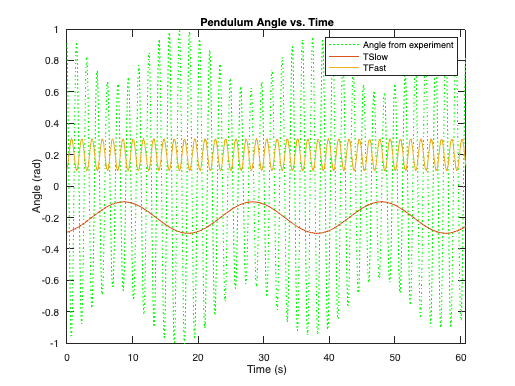

time_vals = rmmissing(raw_data.Time_s_0_2SameAngle);
angle_vals = rmmissing(raw_data.Angle_ChP1_rad_0_2SameAngle);
angle_vals_minus_mean = (angle_vals - mean(angle_vals));
angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
plot(time_vals, angle_vals_minus_mean,':', "Color", "green")
hold on 
fplot(@(x) 0.1*sin(0.32*x - 1.2) - 0.2, [min(time_vals), max(time_vals)])
fplot(@(x) 0.1*sin(4.01*x - 1.2) + 0.2, [min(time_vals), max(time_vals)])
hold off
ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
xlim([min(time_vals), max(time_vals)])
legend("Angle from experiment", "TSlow", "TFast")
title("Pendulum Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")
hold off

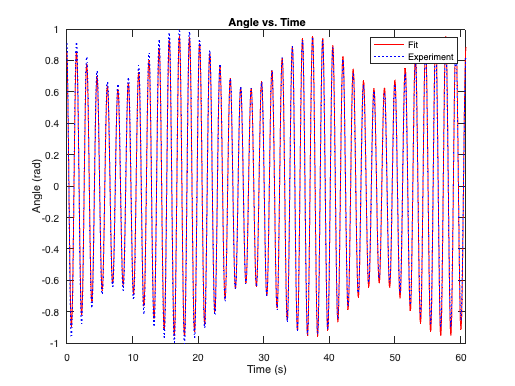

plot(fit_for_0_25_same_angle, "fit")
hold on
plot(time_vals, angle_vals_minus_mean,':', "Color", "blue")
title("Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Fit", "Experiment")
ylim([min(angle_vals_minus_mean), max(angle_vals_minus_mean)])
xlim([min(time_vals), max(time_vals)])
hold off

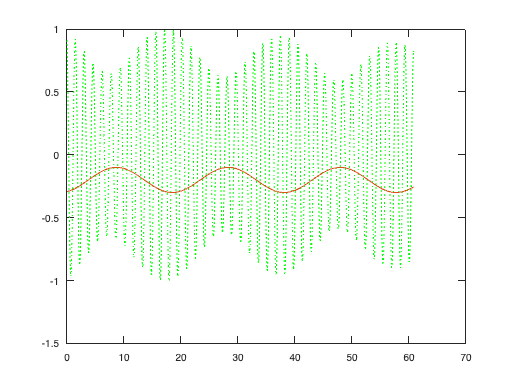

% cftool(time_vals, angle_vals_minus_mean, [], ones(1, length(time_vals)) * 0.0001)


% process_and_plot_pendulum_vals(raw_data.Time_s_0_2SameAngle, raw_data.Angle_ChP1_rad_0_2SameAngle)

function plotted_pendulum_vals = process_and_plot_pendulum_vals(x_vals, y_vals)
    time_vals = rmmissing(x_vals);
    angle_vals = rmmissing(y_vals);
    angle_vals_minus_mean = (angle_vals - mean(angle_vals));
    angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
    plot(time_vals, angle_vals_minus_mean,':', "Color", "green")
    hold on 
    fplot(@(x) 0.1*sin(0.32*x - 1.2) - 0.2, [min(time_vals), max(time_vals)])
    hold off
end
